clear; clc; close all;

set(0,'DefaultAxesFontName','SimHei');      % 坐标轴刻度字体
set(0,'DefaultTextFontName','SimHei');      % 文本对象（标题、标签等）字体

%% =============================
% 1. 用户输入：读取实际全息图（支持任意长方形，不裁剪正方形）
% =============================
[filename, pathname] = uigetfile({'*.bmp;*.tif;*.png;*.jpg','图像文件'; '*.*','所有文件'}, '选择离轴全息图');
if isequal(filename,0)
    disp('用户取消选择');
    return;
end
filepath = fullfile(pathname, filename);
I_raw = imread(filepath);

% 转换为灰度并转为 double 类型（归一化到 [0,1] 区间）
if size(I_raw,3) == 3
    I_raw = rgb2gray(I_raw);
end
I = double(I_raw) / 255;   % 归一化

% --- 【去噪层 1】对原始全息图进行轻微高斯平滑（预处理） ---
sigma_spatial = 0.8; % 空间域高斯标准差，越大越模糊，建议 0.5~1.5
I = imgaussfilt(I, sigma_spatial); 

% 直接保留原图尺寸，不再裁剪正方形
[Ny, Nx] = size(I);
fprintf('全息图尺寸：%d 行 × %d 列（长方形，不裁剪）\n', Ny, Nx);

全息图尺寸：964 行 × 1292 列（长方形，不裁剪）


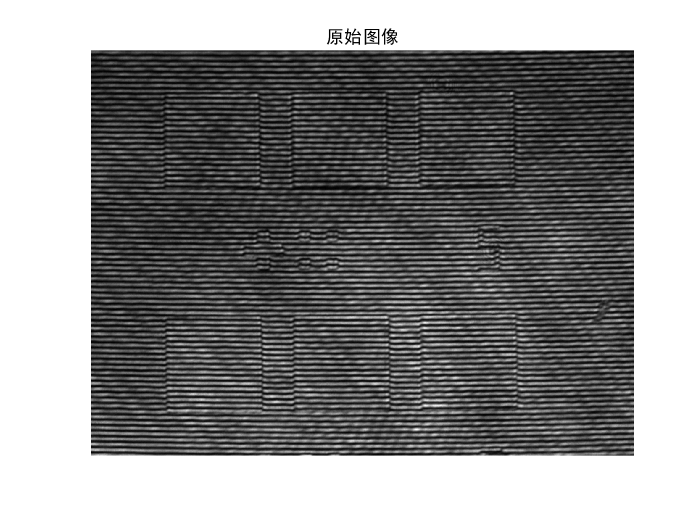


figure;imagesc(I); axis image off;colormap gray; 
title('原始图像','FontName','SimHei');

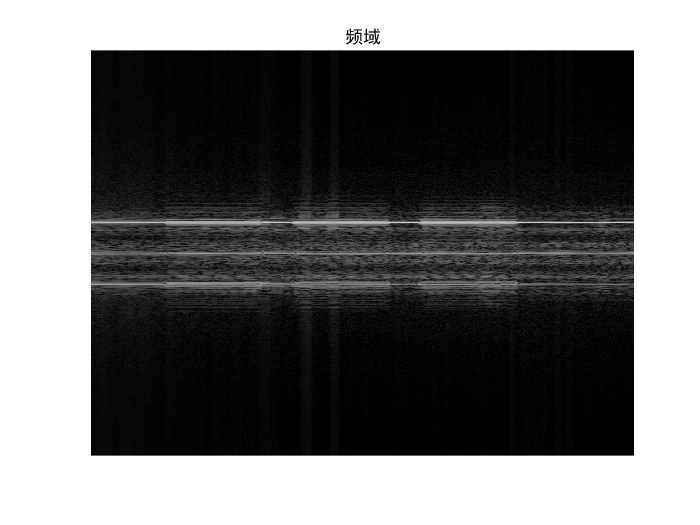


%% =============================
% 2. 物理参数设置（需根据实验调整）
% =============================
dx = 3.5e-6;             % 像元尺寸 (m) ———— 请修改为您的相机像元大小
lambda = 632.8e-9;       % 波长 (m) ———— 请修改为实际激光波长

%% =============================
% 3. 1D FFT（沿垂直方向，假设载频主要在 y 方向）
% =============================
H = fftshift(fft(I,[],1),1);   % 对每一列做 FFT，然后移频
H_amp = abs(H);
figure;
imagesc(log(1+H_amp)); axis image off;colormap gray; title('频域','FontName','SimHei');


%% =============================
% 4. 自动检测 +1 级峰（基于垂直方向频谱投影）
% =============================
center_y = Ny/2 + 1;  % 行方向中心
center_x = Nx/2 + 1;  % 列方向中心

% ---- 对每一行做 FFT 能量统计 ----
spec_v = mean(abs(H), 2);    % 对每一行求均值（垂直方向投影）
spec_v = spec_v(:);           % 列向量

% ---- 屏蔽零级（DC）----
dc_half_width = 15;           % DC 抑制宽度（像素，可调）
spec_v(center_y-dc_half_width : center_y+dc_half_width) = 0;

% ---- 自动寻找 +1 级峰值 ----
[~, v0] = max(spec_v);
u0 = center_x;  % u 方向仍取中心

fprintf('垂直方向自动检测 +1 级位置：u0 = %d, v0 = %d\n', u0, v0);

垂直方向自动检测 +1 级位置：u0 = 647, v0 = 410


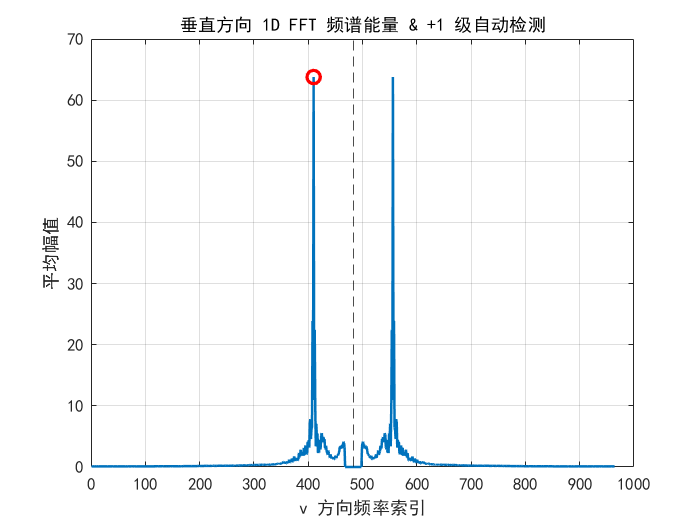


% ---- 可视化垂直方向频谱 ----
figure;
plot(spec_v, 'LineWidth', 1.5); hold on;
plot(v0, spec_v(v0), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
xline(center_y, '--k');
xlabel('v 方向频率索引');
ylabel('平均幅值');
title('垂直方向 1D FFT 频谱能量 & +1 级自动检测','FontName','SimHei');
grid on;

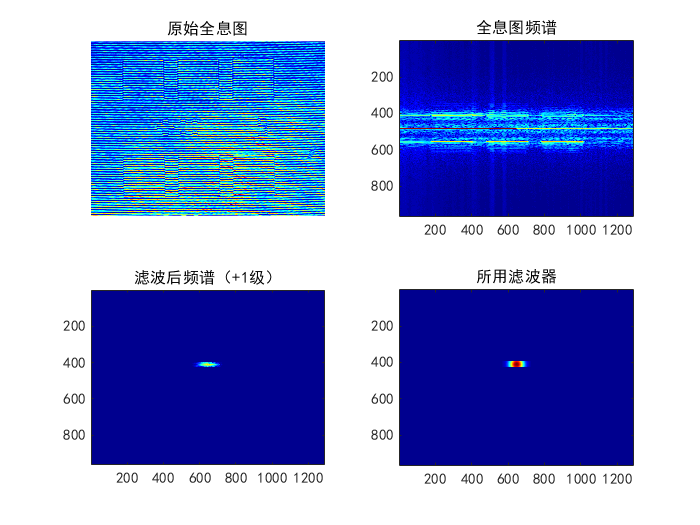


%% =============================
% 5. 设计频域滤波器（可选用矩形、高斯或汉宁窗）
% =============================
% 创建频域坐标网格（分别按 Ny、Nx 生成）
u = (1:Nx) - center_x;
v = (1:Ny) - center_y;
[U, V] = meshgrid(u, v);

% +1 级中心在频域中的偏移量
u_c = u0 - center_x;
v_c = v0 - center_y;

% ---- 矩形滤波器（可选） ----
rect_width  = Nx;     % u 方向宽度（像素）
rect_height = 30;    % v 方向宽度，需根据载频分离程度调整
Rect_1D = zeros(Ny, Nx);
Rect_1D( abs(U - u_c) <= rect_width/2 & abs(V - v_c) <= rect_height/2 ) = 1;

% ---- 高斯窗滤波器（推荐，抑制吉布斯） ----
sigma = 28;          % 高斯窗标准差（像素）
G = exp(-((U - u_c).^2 + (V - v_c).^2) / (2*sigma^2));
filter_used = Rect_1D .* G;

% 频域滤波
Hf = H .* filter_used;

% 显示原始全息图、频谱及滤波后频谱
figure;
subplot(2,2,1); imshow(I, []); title('原始全息图');
subplot(2,2,2); imagesc(log(1+H_amp)); axis image; colormap gray; title('全息图频谱');
subplot(2,2,3); imagesc(log(1+abs(Hf))); axis image; colormap gray; title('滤波后频谱（+1级）');
subplot(2,2,4); imagesc(filter_used); axis image; colormap jet; title('所用滤波器');


%% =============================
% 6. 频谱中心化（将 +1 级移至零频）
% =============================
shift_x = center_x - u0;   % u 方向平移量
shift_y = center_y - v0;   % v 方向平移量
fprintf('频谱平移量：dx = %d, dy = %d\n', shift_x, shift_y);

频谱平移量：dx = 0, dy = 73


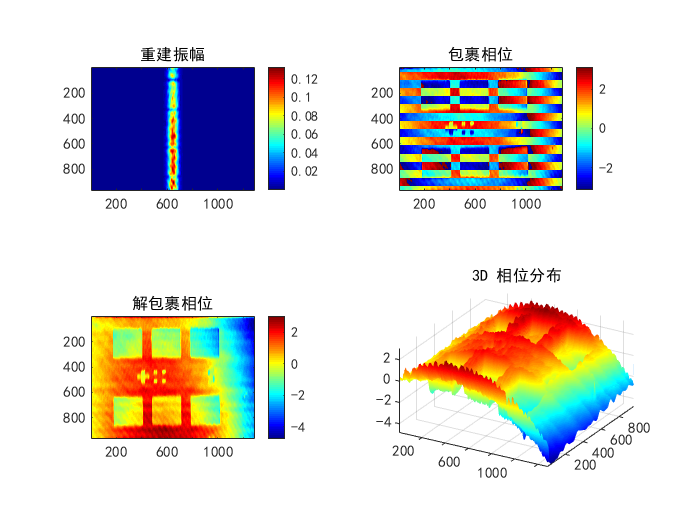


Hf_center = circshift(Hf, [shift_y, shift_x]);

% 逆 FFT 得到重建的物光复振幅
U_rec = ifft(Hf_center, [], 1);

amp_rec = abs(U_rec);
phase_wrapped = angle(U_rec);   % 包裹相位 [-pi, pi]

%% =============================
% 7. 相位解包裹
% =============================
phi_unwrap = least_squares_unwrap_1d_corrected(phase_wrapped, 2);

% 中值滤波去噪
med_window_size = 3; 
phi_unwrap = medfilt2(phi_unwrap, [med_window_size, med_window_size]);

%% =============================
% 8. 结果显示
% =============================
figure;
subplot(2,2,1); imagesc(amp_rec); axis image; colormap gray; colorbar; title('重建振幅');
subplot(2,2,2); imagesc(phase_wrapped); axis image; colormap jet; colorbar; title('包裹相位');
subplot(2,2,3); imagesc(phi_unwrap); axis image; colormap jet; colorbar; title('解包裹相位');
subplot(2,2,4); surf(phi_unwrap, 'EdgeColor','none'); axis tight; view(30,40); title('3D 相位分布');

%% =============================
% 新增：读取背景全息图（无样品）
% =============================
[bg_filename, bg_pathname] = uigetfile({'*.bmp;*.tif;*.png;*.jpg','图像文件'; '*.*','所有文件'}, '选择背景全息图（无样品）');
if isequal(bg_filename,0)
    disp('用户取消选择背景图，将使用边缘拟合方法');
    use_bg = false;
else
    use_bg = true;
    bg_filepath = fullfile(bg_pathname, bg_filename);
    I_bg_raw = imread(bg_filepath);
    if size(I_bg_raw,3) == 3
        I_bg_raw = rgb2gray(I_bg_raw);
    end
    I_bg = double(I_bg_raw) / 255;
    I_bg = imgaussfilt(I_bg, sigma_spatial);  % 与样品图相同的预处理
    fprintf('背景图尺寸：%d × %d\n', size(I_bg,1), size(I_bg,2));

    % 确保背景图尺寸与样品图一致
    if any(size(I_bg) ~= [Ny, Nx])
        error('背景图和样品图尺寸不一致，请检查！');
    end
end

背景图尺寸：964 × 1292




[Ny, Nx] = size(I_bg);
fprintf('全息图尺寸：%d 行 × %d 列（长方形，不裁剪）\n', Ny, Nx);

全息图尺寸：964 行 × 1292 列（长方形，不裁剪）


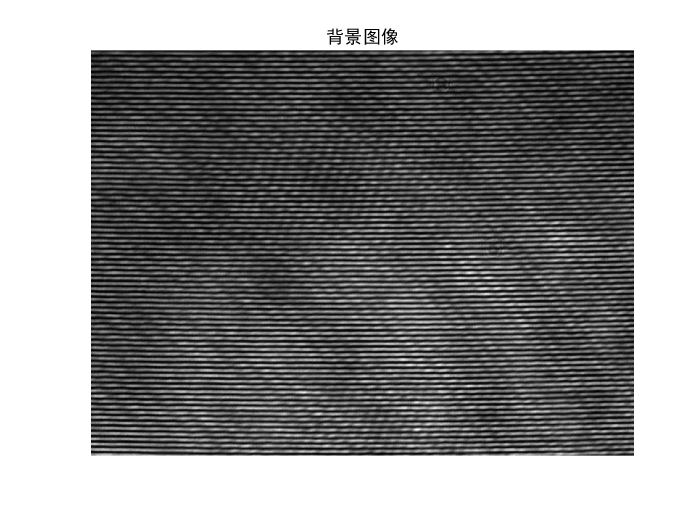

figure;imagesc(I_bg); axis image off;colormap gray; 
title('背景图像','FontName','SimHei');


H_bg = fftshift(fft(I_bg,[],1),1);
Hf_bg = H_bg .* filter_used;

shift_x = center_x - u0;   % u 方向平移量
shift_y = center_y - v0;   % v 方向平移量
fprintf('频谱平移量：dx = %d, dy = %d\n', shift_x, shift_y);

频谱平移量：dx = 0, dy = 73


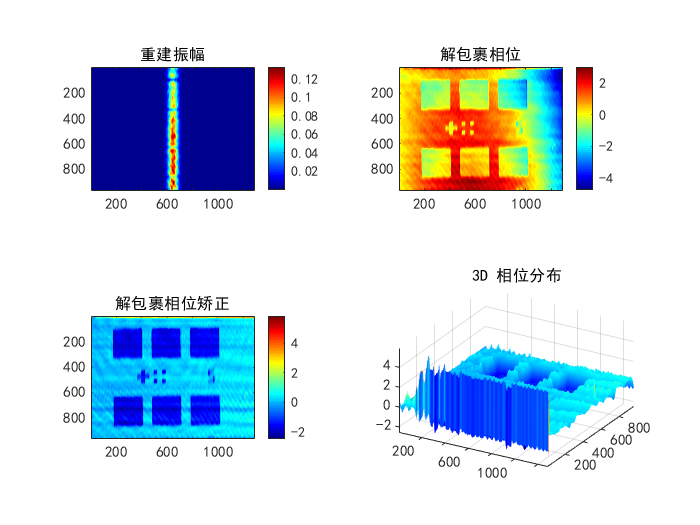

% 频谱中心化
Hf_center_bg = circshift(Hf_bg, [shift_y, shift_x]);

% 逆 FFT 得到重建的物光复振幅
U_rec_bg = ifft(Hf_center_bg, [], 1);
phase_bg_wrapped = angle(U_rec_bg);   % 包裹相位 [-pi, pi]
%% =============================
% 7. 相位解包裹
% =============================
%% 背景相位解包裹
phi_bg_unwrap = least_squares_unwrap_1d_corrected(phase_bg_wrapped, 2);
phi_bg_unwrap = medfilt2(phi_bg_unwrap, [med_window_size, med_window_size]);

phi_corrected = phi_unwrap - phi_bg_unwrap;


figure;
subplot(2,2,1); imagesc(amp_rec); axis image; colormap gray; colorbar; title('重建振幅');
subplot(2,2,2); imagesc(phi_unwrap); axis image; colormap jet; colorbar; title('解包裹相位');
subplot(2,2,3); imagesc(phi_corrected); axis image; colormap jet; colorbar; title('解包裹相位矫正');
subplot(2,2,4); surf(phi_corrected, 'EdgeColor','none'); axis tight; view(30,40); title('3D 相位分布');

% %% =============================
% % 生成坐标网格（长方形版）
% %% =============================
% [X, Y] = meshgrid( (1:Nx) - center_x, (1:Ny) - center_y );
% %% =============================
% % 【核心修改】9. 二次多项式校正（消除穹顶畸变）
% % =============================
% % 1. 创建背景掩模（利用图像边缘，假设边缘无样品）
% background_mask = zeros(Ny, Nx);
% border_width = 30; % 边缘宽度
% background_mask(1:border_width, :)             = 1;
% background_mask(end-border_width+1:end, :)      = 1;
% background_mask(:, 1:border_width)             = 1;
% background_mask(:, end-border_width+1:end)      = 1;
% 
% % 2. 提取背景点
% bg_points = find(background_mask);
% bg_X = X(bg_points);
% bg_Y = Y(bg_points);
% bg_phi = phi_unwrap(bg_points);
% 
% % 3. 拟合二次多项式
% A = [bg_X(:), bg_Y(:), bg_X(:).^2, bg_Y(:).^2, bg_X(:).*bg_Y(:), ones(length(bg_X), 1)];
% coeffs = A \ bg_phi(:); 
% 
% a1 = coeffs(1);    % x
% a2 = coeffs(2);    % y
% a3 = coeffs(3);    % x²
% a4 = coeffs(4);    % y²
% a5 = coeffs(5);    % xy
% a0 = coeffs(6);    % 常数
% 
% % 4. 拟合畸变相位
% phi_fit = a1*X + a2*Y + a3*X.^2 + a4*Y.^2 + a5*X.*Y + a0;
% % 5. 校正
% phi_corrected = phi_unwrap - phi_fit;
% 
% %% =============================
% % 10. 边缘裁剪
% % =============================
% crop_pixels = 25;
% phi_cropped   = phi_corrected(crop_pixels+1:end-crop_pixels, crop_pixels+1:end-crop_pixels);
% X_cropped     = X(crop_pixels+1:end-crop_pixels, crop_pixels+1:end-crop_pixels);
% Y_cropped     = Y(crop_pixels+1:end-crop_pixels, crop_pixels+1:end-crop_pixels);
% 
% %% =============================
% % 11. 可视化结果（优化版）
% % =============================
% figure('Name','穹顶校正全流程');
% % 1. 原始解包裹相位
% subplot(2,3,1);
% surf(X*dx*1000, Y*dx*1000, phi_unwrap, 'EdgeColor', 'none');
% xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('相位 (rad)');
% title('原始解包裹相位','FontName','SimHei');
% colormap jet; colorbar; view(30, 40); grid on; axis tight;
% 
% % 2. 拟合的“倾斜+穹顶”畸变面
% subplot(2,3,2);
% surf(X*dx*1000, Y*dx*1000, phi_fit, 'EdgeColor', 'none');
% xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('相位 (rad)');
% title('拟合畸变面(倾斜+穹顶)','FontName','SimHei');
% colormap jet; colorbar; view(30, 40); grid on; axis tight;
% 
% % 3. 校正后相位
% subplot(2,3,3);
% surf(X*dx*1000, Y*dx*1000, phi_corrected, 'EdgeColor', 'none');
% xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('相位 (rad)');
% title('校正后相位','FontName','SimHei');
% colormap jet; colorbar; view(30, 40); grid on; axis tight;
% 
% % 4. 原始2D
% subplot(2,3,4);
% imagesc(X(1,:)*dx*1000, Y(:,1)*dx*1000, phi_unwrap); axis image off;
% colormap jet; colorbar;
% title('原始解包裹相位(2D)','FontName','SimHei');
% 
% % 5. 校正后2D
% subplot(2,3,5);
% imagesc(X(1,:)*dx*1000, Y(:,1)*dx*1000, phi_corrected); axis image off;
% colormap jet; colorbar;
% title('校正后相位(2D)','FontName','SimHei');
% 
% % 6. 裁剪后2D
% subplot(2,3,6);
% imagesc(X_cropped(1,:)*dx*1000, Y_cropped(:,1)*dx*1000, phi_cropped); axis image off;
% colormap jet; colorbar;
% title('裁剪后校正相位','FontName','SimHei');
% 
% % 单独展示最终3D结果
% figure('Name','最终3D结果');
% surf(X_cropped*dx*1000, Y_cropped*dx*1000, phi_cropped, 'EdgeColor', 'none');
% xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('相位 (rad)');
% title('最终校正相位(3D)','FontName','SimHei');
% colormap jet; colorbar; view(30, 40); grid on; axis tight;
% shading interp;
% 
% % 可选：绘制水平和垂直方向相位剖面
% mid_row = round(Ny/2);
% mid_col = round(Nx/2);
% figure;
% subplot(1,2,1); plot(phi_corrected(280,:), 'b-', 'LineWidth',1.5); xlabel('像素'); ylabel('相位 (rad)'); title('水平方向剖面（中间行）'); grid on;
% subplot(1,2,2); plot(phi_corrected(:,190), 'r-', 'LineWidth',1.5); xlabel('像素'); ylabel('相位 (rad)'); title('垂直方向剖面（中间列）'); grid on;
% 